# ECG Classification with Continuous Wavelet Transform

This example shows how you can build a model using transfer learning techniques to classify signal data.  We will use a Wavelet Transform to generate a time-frequency representation of a signal.  The Wavelet Transform greatly enhances the spectral information present as a function of time in the signal and we can save this information as an image to be used with a convolutional neural net.  The convolutional neural network will be trained to detect whether an echocardiogram (ECG) signal comes from a heart with: *Normal Sinus Rhythm (NSR), Arrhythmia (ARR) or Congestive Heart Failure (CHF)*.

## Introduction

The wavelet transform allows us to approximate a signal using the sum of short-lived waves (wavelets).  The advantage of using wavelets for time-frequency analysis is the wavelet transform's ability to capture abrupt changes without paying in time or frequency.  

%prj = currentProject;

## **I. Prepare the Signals**

### Load Signals

The data are 162 sample signals, sampled at a frequency (Fs) of 128Hz.

load(fullfile(pwd, "data", "SignalData.mat"))

These signals come in three categories:

unique(ECGData.Labels)

ans = 3×1 categorical array
     ARR 
     CHF 
     NSR 

Where `ARR` refers to signals with an abnormal heart rhythm (*Arrhythmia*), `CHF` stands for Congestive Heart Failure, and `NSR` refers to a normal heart rhythm (*Normal Sinus Rhythm*).

### Visualize Signals

Use the [Signal Analyzer App](https://www.mathworks.com/help/releases/R2019a/signal/ref/signalanalyzer-app.html) to explore the time and frequency of a signal.  You can open the app from the Apps tab or by running `signalAnalyzer`.  

## 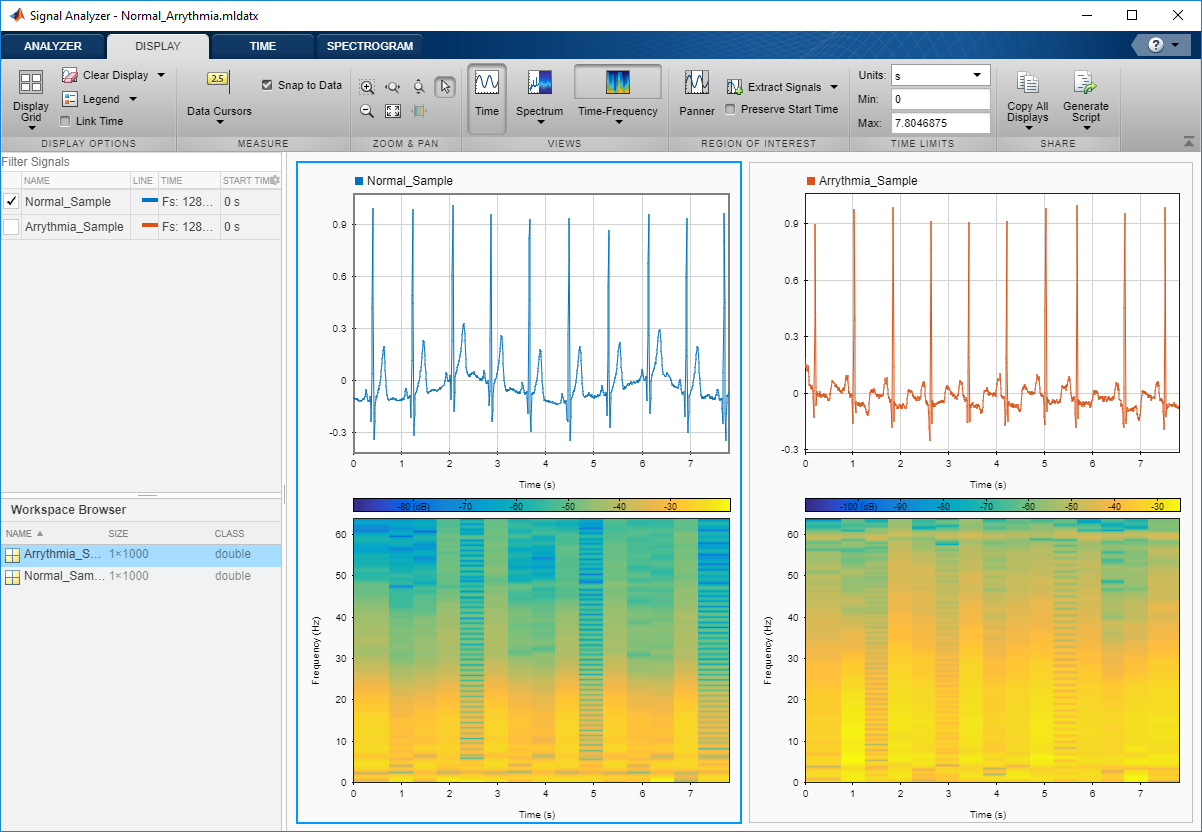

### Challenges with Traditional Time Frequency Analysis Approach

Using tradition time and frequency analysis can tend to result in poorly resolved signals along time or frequency.  This trade off is something we want to tackle.

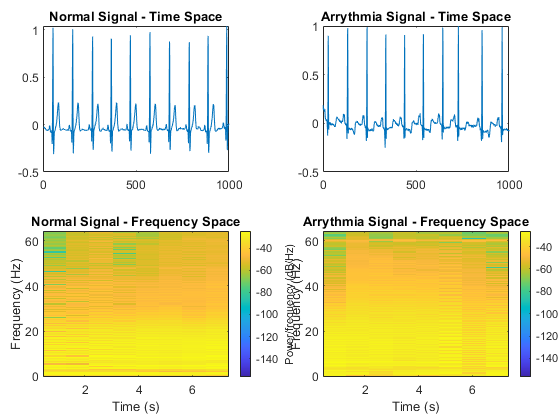

clf
tiledlayout(2, 2, "Padding", "compact")
nexttile
plot(Normal_Sample_Class_I)
title('Normal Signal - Time Space')

nexttile
plot(Arrythmia_Sample_Class_II)
title('Arrythmia Signal - Time Space')

nexttile
spectrogram(Normal_Sample_Class_I, [], [], [], Fs, 'yaxis');
title('Normal Signal - Frequency Space')

nexttile
spectrogram(Arrythmia_Sample_Class_II, [], [], [], Fs, 'yaxis');
title('Arrythmia Signal - Frequency Space')

Notice although the signals have different meaning, a traditional time-frequency analysis does not help identify the difference between the two signals.

### Time Frequency Analysis using Wavelets

When you work with real-world signals that have features that are occuring at different scales (like EKG), localizing the spectral contents in time is important as this could provide a lot of insight into your signals. 

The Continuous Wavelet Transform can help you obtain sharp time-frequency representation of your signal - without you having to specify any parameters like window size etc. 

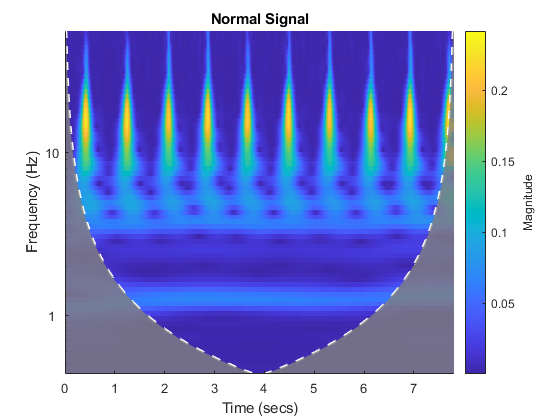

clf
cwt(Normal_Sample_Class_I, Fs)
title('Normal Signal')

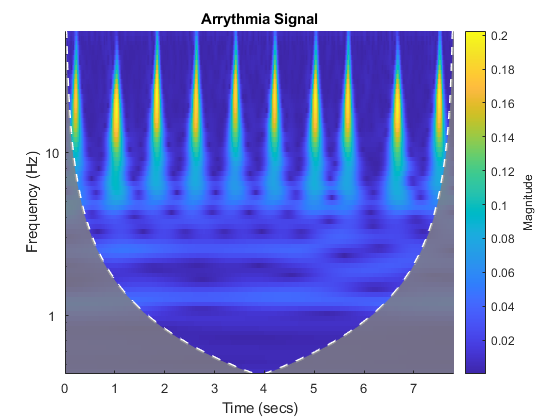

clf
cwt(Arrythmia_Sample_Class_II, Fs)
title('Arrythmia Signal')

Notice how the spectral details have been enhanced with the Wavelet Transform. For instance,  

- The peaks are well separated 

- The irregular separation of the yellow bars distinguishes the Arrythmia Signal from the Normal Signal

- There is some activity going on in the lower half of the representation for Arrythmia which is not the case with the Normal Signal

**We can save these representations as images and train a preconfigured Convolutional Neural Network.**

## **II. Generate Wavelet Time-Frequency Representations**

### Create a Filter Bank

If we want to compute the wavelet transform on multiple signals, using a precomputed filter bank can greatly speed up the process.

sig = ECGData.Data(1,:);

fb =   cwtfilterbank with properties:

      VoicesPerOctave: 10
              Wavelet: 'morse'
    SamplingFrequency: 128
       SamplingPeriod: []
         PeriodLimits: []
         SignalLength: 65536
      FrequencyLimits: []
        TimeBandwidth: 60
    WaveletParameters: []
             Boundary: 'reflection'

signalLength = length(sig);
fb = cwtfilterbank('SignalLength', signalLength, 'SamplingFrequency', Fs)

### Compute the Wavelet Transform 

[wt, f] = fb.wt(sig);

#### **Generate Time-Frequency Visualizations for all Signals**

Open the [`PrepareSignalData.mlx`](matlab:edit('PrepareSignalData.mlx');) file.

### Split the Time-Frequency Representation Images into Training and Test Sets

The `imageDatastore` points at directories of labeled data and will automatically create training and testing sets.  Image datastores can be directly passed into the neural network training function.  The `ReadFcn` makes sure the image size agrees with the first input layer size requirement.

readFcn = @(imagefilename)imresize(imread(imagefilename), [227 227]);
allImages = imageDatastore(fullfile(prj.RootFolder,"data", "CWT"), ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames', ...
    'ReadFcn', readFcn);
[trainingImages, testImages] = splitEachLabel(allImages, 0.8, 'randomize');

## **III. Train a Pre-Trained Network**

### **Initialize the Network **

We'll load in the pretrained `alexnet` network.  This can be downloaded from the add-ons manager.  In order to retrain just the last few layers, we will replace them with a new `fullyConnectedLayer` and a new `classificationLayer`.

alex = alexnet;
layers = alex.Layers;
layers(23) = fullyConnectedLayer(3);
layers(25) = classificationLayer;

You can also perform this operation graphically by using the [Deep Network Designer](https://www.mathworks.com/help/releases/R2019a/deeplearning/ref/deepnetworkdesigner-app.html) App. 

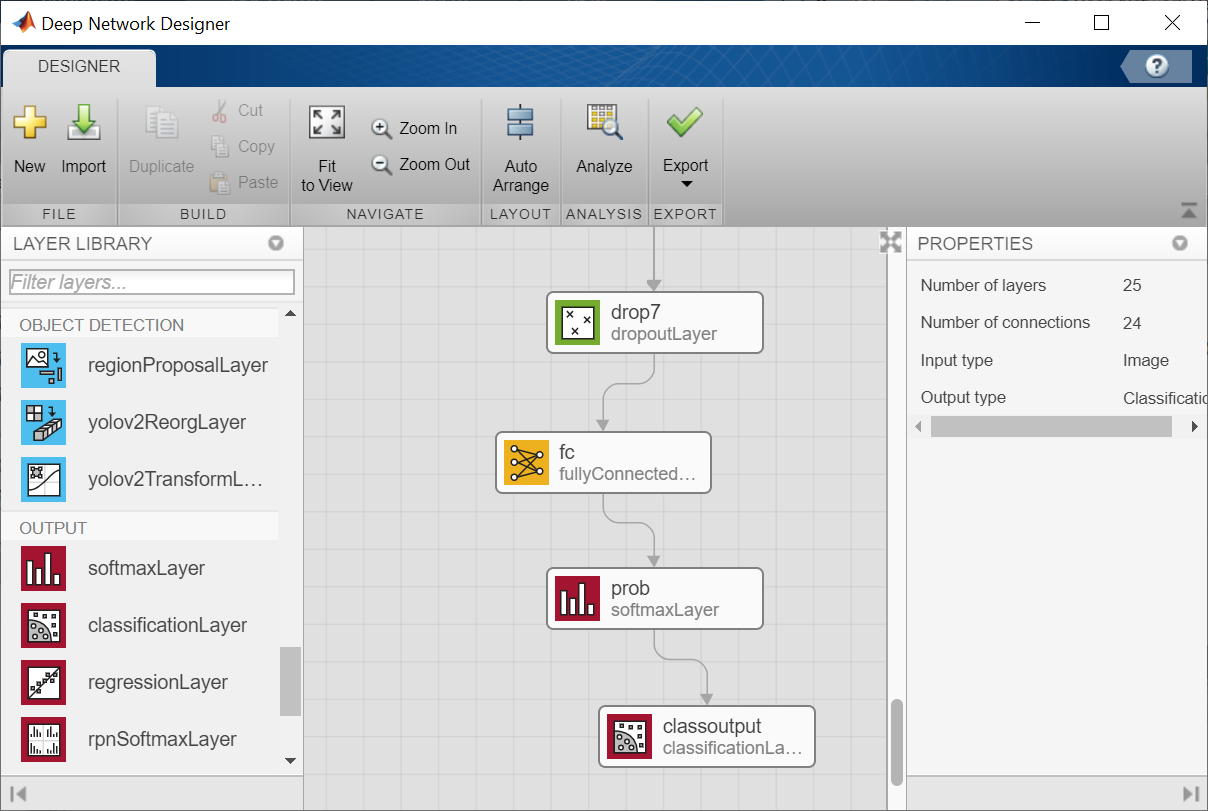

### **Train the Network**

Retrain the network. 

retrain = false;
 
% if retrain
%     opts = trainingOptions('sgdm', ...
%         'InitialLearnRate', 0.0001, ...
%         'MaxEpochs', 12, ...
%         'MiniBatchSize', 10, ...
%         'Plots', 'training-progress');
%     ECGNet = trainNetwork(trainingImages, layers_1, opts);
% else

 Optionally, [watch the training video](matlab:system('training.mp4');).   

%     load(fullfile(prj.RootFolder, "ECGDeepLearningWithCWT", "ECGNet.mat"))
% end

## **Evaluate the Trained Model**

Use the trained model on the test image set and show the confusion matrix.

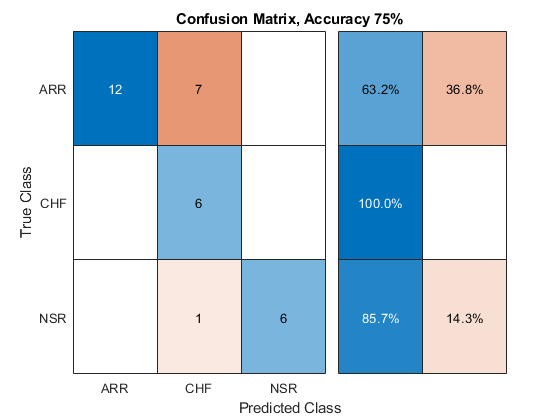

predictedLabels  = classify(ECGNet, testImages);
accuracy = sum(predictedLabels == testImages.Labels) / numel(predictedLabels);

clf
cm = confusionchart(testImages.Labels, predictedLabels, ...

    "Title", "Confusion Matrix, Accuracy " + accuracy*100 + "%", ...
    "RowSummary", "row-normalized");

## Summary

To wrap up, we have seen how you can generate sharp time-frequency representations and customize / leverage existing deep networks to build a signal classifier. Using just two lines of code you can generate sharp time-frequency representationsfor real world signals and use it for building classifiers using deep networks. 

*Copyright 2020 The MathWorks, Inc.*